documents = tokenizedDocument(SmsCollection(:,2));
bag = bagOfWords(documents)

bag =   bagOfWords with properties:

          Counts: [5574×11238 double]
      Vocabulary: [1×11238 string]
        NumWords: 11238
    NumDocuments: 5574


tbl = topkwords(bag,10)

tbl = 10×2 table
    Word     Count
    _____    _____

    "."      10734
    "to"      2159
    ","       1940
    "you"     1834
    "?"       1549
    "I"       1543
    "!"       1397
    "a"       1342
    "�"       1313
    "the"     1212


newBag = removeWords(bag,stopWords)

newBag =   bagOfWords with properties:

          Counts: [5574×11067 double]
      Vocabulary: [1×11067 string]
        NumWords: 11067
    NumDocuments: 5574


tbl2 = topkwords(newBag,10)

tbl2 = 10×2 table
    Word    Count
    ____    _____

    "."     10734
    ","      1940
    "?"      1549
    "I"      1543
    "!"      1397
    "�"      1313
    "&"       922
    "u"       797
    ";"       770
    ":"       727


newBag2 = removeWords(newBag,[".", ",", ";", "?", "!", ":", ")", "&"])

newBag2 =   bagOfWords with properties:

          Counts: [5574×11059 double]
      Vocabulary: [1×11059 string]
        NumWords: 11059
    NumDocuments: 5574


tbl3 = topkwords(newBag2,10)

tbl3 = 10×2 table
     Word     Count
    ______    _____

    "I"       1543 
    "�"       1313 
    "u"        797 
    "2"        506 
    "call"     397 
    "U"        371 
    "get"      336 
    "/"        329 
    "gt"       318 
    "lt"       316 


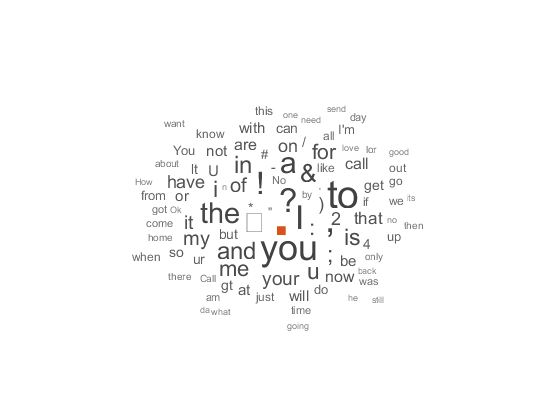

figure
wordcloud(bag);

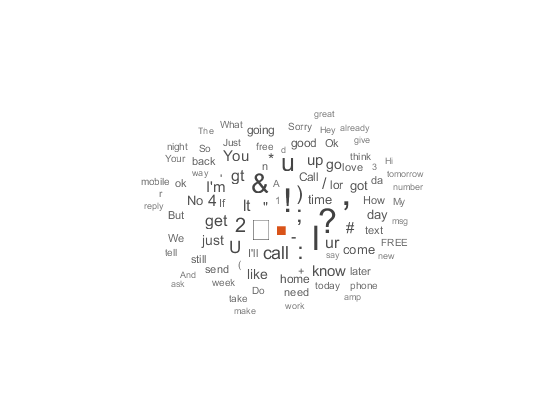

figure
wordcloud(newBag);

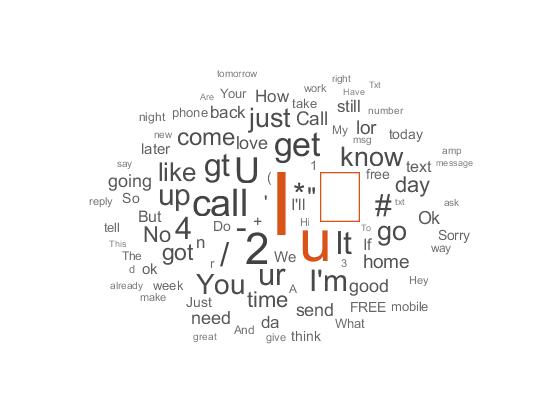

figure
wordcloud(newBag2);

m = 1;
n = 1;
for i = 1:length(SmsCollection)
    if SmsCollection(i,1)=='ha'
        spaha(i) = 1;
        ham(n,1) = SmsCollection(i,2);
        n = n + 1;
    else
        spaha(i) = 0;
        spam(m,1) = SmsCollection(i,2);
        m = m + 1;
    end
        
end

spaha = logical(spaha');


documentss = tokenizedDocument(spam);
bags = bagOfWords(documentss)

bags =   bagOfWords with properties:

          Counts: [749×3636 double]
      Vocabulary: [1×3636 string]
        NumWords: 3636
    NumDocuments: 749


tbls = topkwords(bags,10)

tbls = 10×2 table
     Word     Count
    ______    _____

    "."       1170 
    "�"        643 
    "to"       611 
    "!"        545 
    ","        379 
    "a"        360 
    "/"        286 
    "call"     188 
    "you"      187 
    "your"     187 


newBags = removeWords(bags,stopWords)

newBags =   bagOfWords with properties:

          Counts: [749×3520 double]
      Vocabulary: [1×3520 string]
        NumWords: 3520
    NumDocuments: 749


tbl2s = topkwords(newBags,10)

tbl2s = 10×2 table
     Word     Count
    ______    _____

    "."       1170 
    "�"        643 
    "!"        545 
    ","        379 
    "/"        286 
    "call"     188 
    "2"        186 
    "&"        178 
    "?"        174 
    ":"        161 


newBag2s = removeWords(newBags,[".", ",", ";", "?", "!","&", ":"])

newBag2s =   bagOfWords with properties:

          Counts: [749×3513 double]
      Vocabulary: [1×3513 string]
        NumWords: 3513
    NumDocuments: 749


tbl3s = topkwords(newBag2s,10)

tbl3s = 10×2 table
     Word     Count
    ______    _____

    "�"        643 
    "/"        286 
    "call"     188 
    "2"        186 
    "Call"     138 
    "4"        124 
    "FREE"     116 
    "*"        115 
    "ur"       107 
    "+"         98 


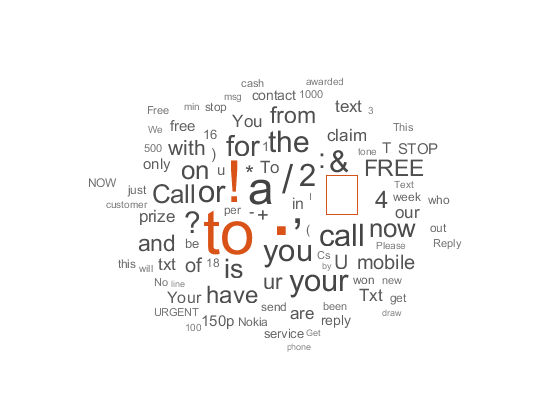

figure
wordcloud(bags);

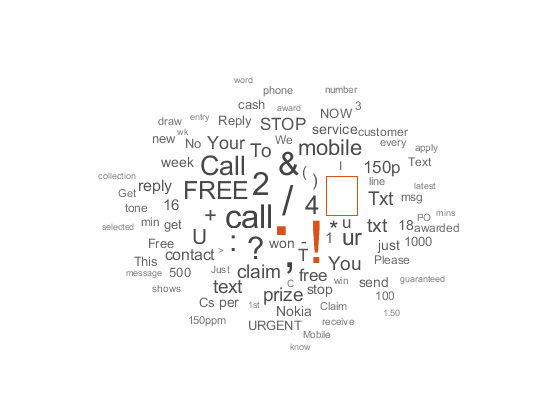

figure
wordcloud(newBags);

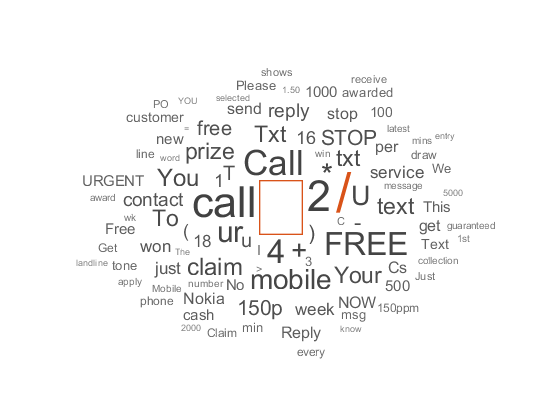

figure
wordcloud(newBag2s);



documentsh = tokenizedDocument(ham);
bagh = bagOfWords(documentsh)

bagh =   bagOfWords with properties:

          Counts: [4825×8824 double]
      Vocabulary: [1×8824 string]
        NumWords: 8824
    NumDocuments: 4825


tblh = topkwords(bagh,10)

tblh = 10×2 table
    Word     Count
    _____    _____

    "."      9564 
    "you"    1647 
    ","      1561 
    "to"     1548 
    "I"      1503 
    "?"      1375 
    "the"    1034 
    "a"       982 
    "!"       852 
    "i"       820 


newBagh = removeWords(bagh,stopWords)

newBagh =   bagOfWords with properties:

          Counts: [4825×8654 double]
      Vocabulary: [1×8654 string]
        NumWords: 8654
    NumDocuments: 4825


tbl2h = topkwords(newBagh,10)

tbl2h = 10×2 table
    Word    Count
    ____    _____

    "."     9564 
    ","     1561 
    "I"     1503 
    "?"     1375 
    "!"      852 
    ";"      768 
    "&"      744 
    "u"      735 
    "�"      670 
    ":"      566 


newBag2h = removeWords(newBagh,[".", ",", ";", "?", "!","&", ":"])

newBag2h =   bagOfWords with properties:

          Counts: [4825×8647 double]
      Vocabulary: [1×8647 string]
        NumWords: 8647
    NumDocuments: 4825


tbl3h = topkwords(newBag2h,10)

tbl3h = 10×2 table
    Word     Count
    _____    _____

    "I"      1503 
    "u"       735 
    "�"       670 
    ")"       433 
    "2"       320 
    "gt"      318 
    "lt"      316 
    "get"     291 
    "I'm"     281 
    "#"       281 


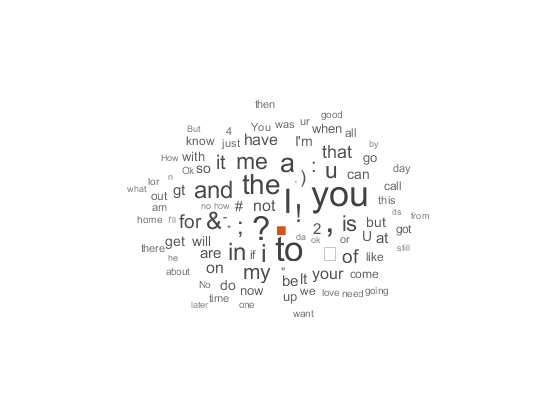

figure
wordcloud(bagh);

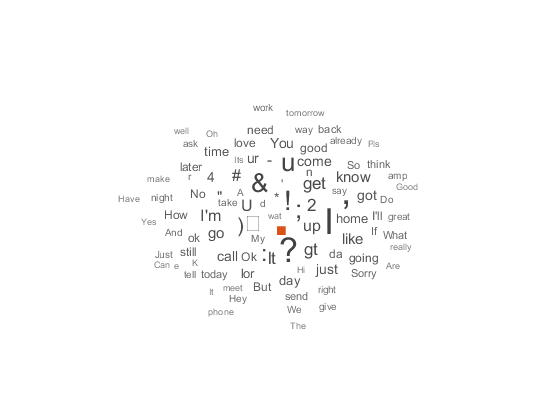

figure
wordcloud(newBagh);

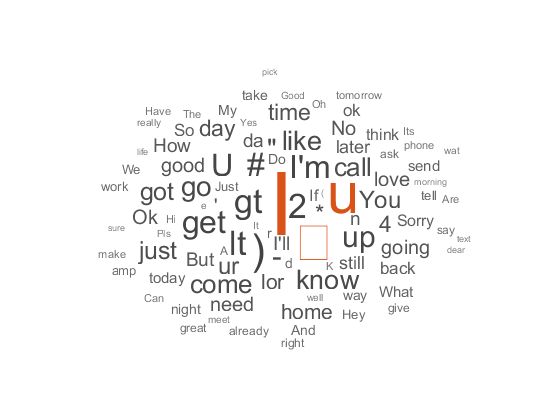

figure
wordcloud(newBag2h);

cvp = cvpartition(length(SmsCollection),'Holdout',0.05)

cvp = Hold-out cross validation partition
   NumObservations: 5574
       NumTestSets: 1
         TrainSize: 5296
          TestSize: 278

idxTrain = training(cvp); % Extract training set indices

mdl = fitclinear(newBag2.Counts(idxTrain),spaha(idxTrain))

mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: -4.2809e-04
              Bias: 1.0000
            Lambda: 1.8882e-04
           Learner: 'svm'


  Properties, Methods



idxTest = test(cvp); % Extract test set indices
labels = predict(mdl,newBag2.Counts(idxTest));
L = loss(mdl,newBag2.Counts(idxTest),spaha(idxTest))

L = 0.1369

cvp = cvpartition(length(SmsCollection),'Holdout',0.05)

cvp = Hold-out cross validation partition
   NumObservations: 5574
       NumTestSets: 1
         TrainSize: 5296
          TestSize: 278

idxTrain = training(cvp); % Extract training set indices

mdl = fitclinear(newBag.Counts(idxTrain),spaha(idxTrain))

mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: -6.8933e-05
              Bias: 1.0000
            Lambda: 1.8882e-04
           Learner: 'svm'


  Properties, Methods



idxTest = test(cvp); % Extract test set indices
labels = predict(mdl,newBag.Counts(idxTest));
L = loss(mdl,newBag.Counts(idxTest),spaha(idxTest))

L = 0.1314

cvp = cvpartition(length(SmsCollection),'Holdout',0.05)

cvp = Hold-out cross validation partition
   NumObservations: 5574
       NumTestSets: 1
         TrainSize: 5296
          TestSize: 278

idxTrain = training(cvp); % Extract training set indices

mdl = fitclinear(bag.Counts(idxTrain),spaha(idxTrain))

mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: 5.0279e-04
              Bias: 1.0000
            Lambda: 1.8882e-04
           Learner: 'svm'


  Properties, Methods



idxTest = test(cvp); % Extract test set indices
labels = predict(mdl,bag.Counts(idxTest));
L = loss(mdl,bag.Counts(idxTest),spaha(idxTest))

L = 0.1333